## Opgave 1

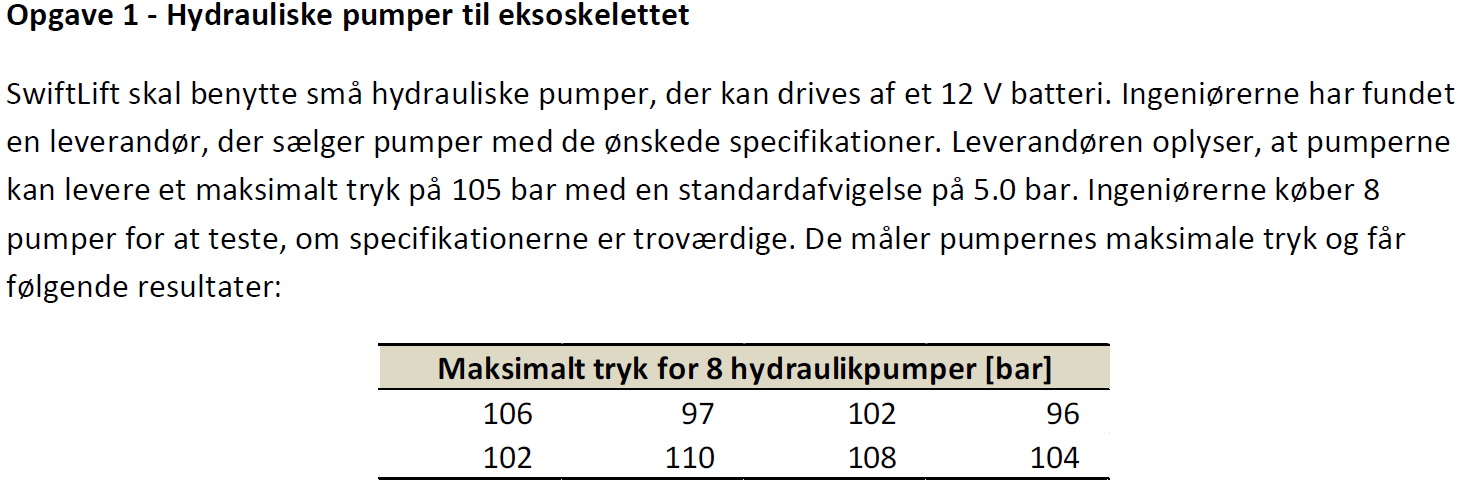

### a)

clear
middel_lev = 105;
std_lev = 5;
n = 8; 
data = xlsread("Eksamens sæt\18E\Data_M4STI1_2018E.xlsx");
data_size = size(data);
tryk = data(1:8,1)

tryk =    106
    97
   102
    96
   102
   110
   108
   104


middel = mean(tryk)

middel = 103.1250

Median = median(tryk)

Median = 103

sigma_2 = var(tryk)

sigma_2 = 24.4107

sigma = std(tryk)

sigma = 4.9407

data_min = min(tryk)

data_min = 96

data_max = max(tryk)

data_max = 110

### b)

Præsentér data fra stikprøven med et stem-and-leaf diagram, et boksplot og et histogram. Hvad fortæller diagrammerne om stikprøven?

stemleafplot(tryk,0)

   9 | 6 7
  10 | 2 2 4 6 8
  11 | 0
key: 36|5 = 365
stem unit: 10
leaf unit: 1


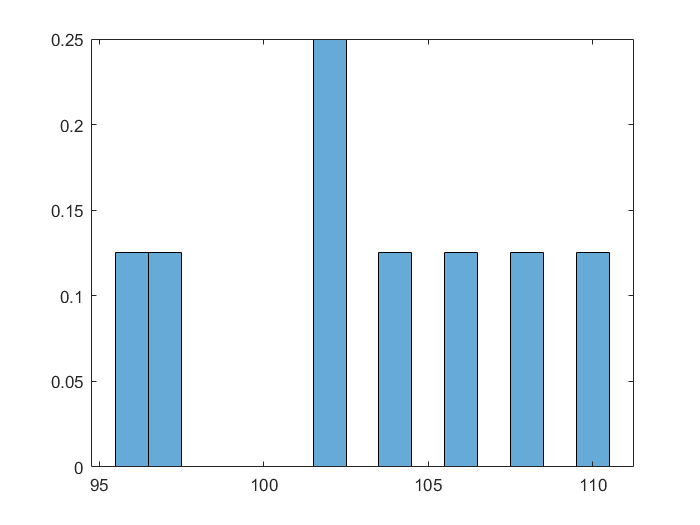

histogram(tryk, "Normalization","probability") % bins,

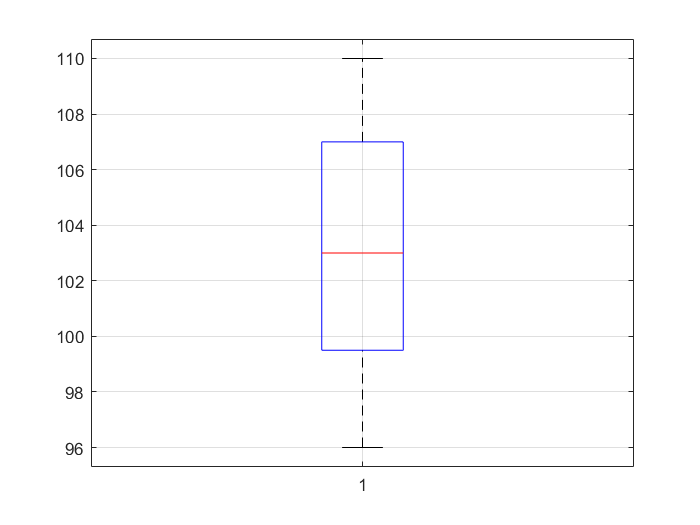

boxplot(tryk)
grid()

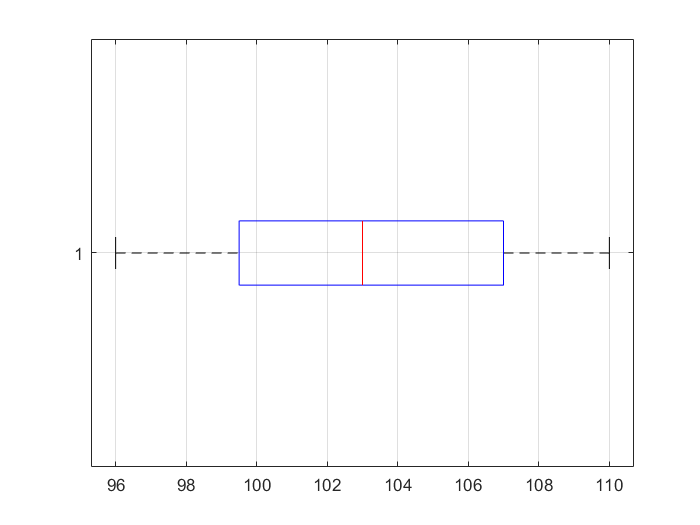

boxplot(tryk,'Orientation',"horizontal")
grid()

### c)

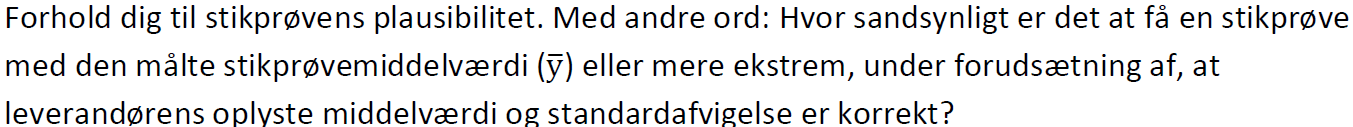

Her er $\bar Y$ Vores stik prøve og de andre værdier er de forventede eller leverendørens tal.

Y_norm = norm(middel, sigma_2/n)

Y_norm = 103.1250

Z = (Y_norm - middel_lev)/(std_lev/sqrt(n))

Z = -1.0607

Dette er den stadardiserede standard afvigelse

p = 2*(1 - normcdf(abs(Z))) 

p = 0.2888

Hvis leverandørens specifikationer af pumpernes middelværdi og standardafvigelse er korrekte, så vil vi forvente at få en stikprøve som den pågældende, eller mere ekstrem, i knap 29% af tilfældene. Det er ikke usandsynligt, så vi må tro på specifikationerne.

### d)

Hvad kan du konkludere om pumperne på baggrund af stikprøven, og under hvilke antagelser?

Stikprøven underbygger leverandørens specifikationer. I delspørgsmål a. så vi, at stikprøvens gennemsnit og standardafvigelse er tæt på de oplyste værdier. I delspørgsmål c. så vi, at stikprøven er sandsynlig for en population med 𝜇𝜇=105 bar og 𝜎𝜎=5.0 bar. Det konkluderede vi under antagelse af den centrale grænseværdisætning, som forudsætter, at 𝑛𝑛=8 er tilstrækkelig stor. I delspørgsmål b. så vi, at stikprøven kommer fra en pæn fordeling: symmetrisk, med et enkelt toppunkt og ingen outliers. Derfor er 𝑛𝑛=8 stor nok til at den centrale grænseværdisætning er opfyldt. Dette bekræftes yderligere af et normalfordelingsplot, der viser at observationerne ligger nogenlunde på en ret linje:

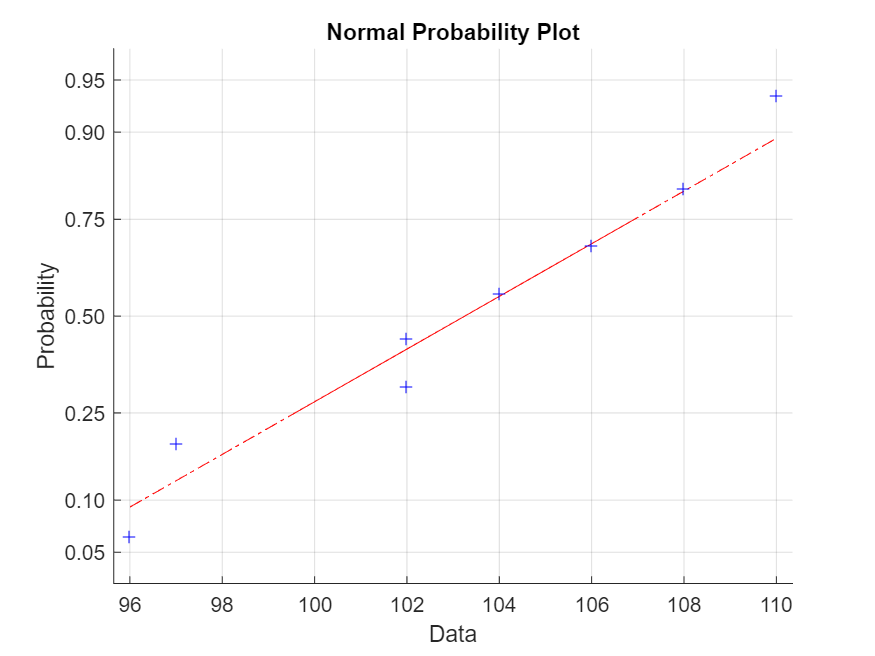

normplot(tryk)

### I de følgende delspørgsmål skal du benytte stikprøven og se bort fra leverandørens specifikationer af middelværdi og standardafvigelse for pumperne.

### e)

Beregn et 99 % konfidensinterval for middelværdien

### f)

Beregn et 99 % prædiktionsinterval

### g)

## Opgave 2

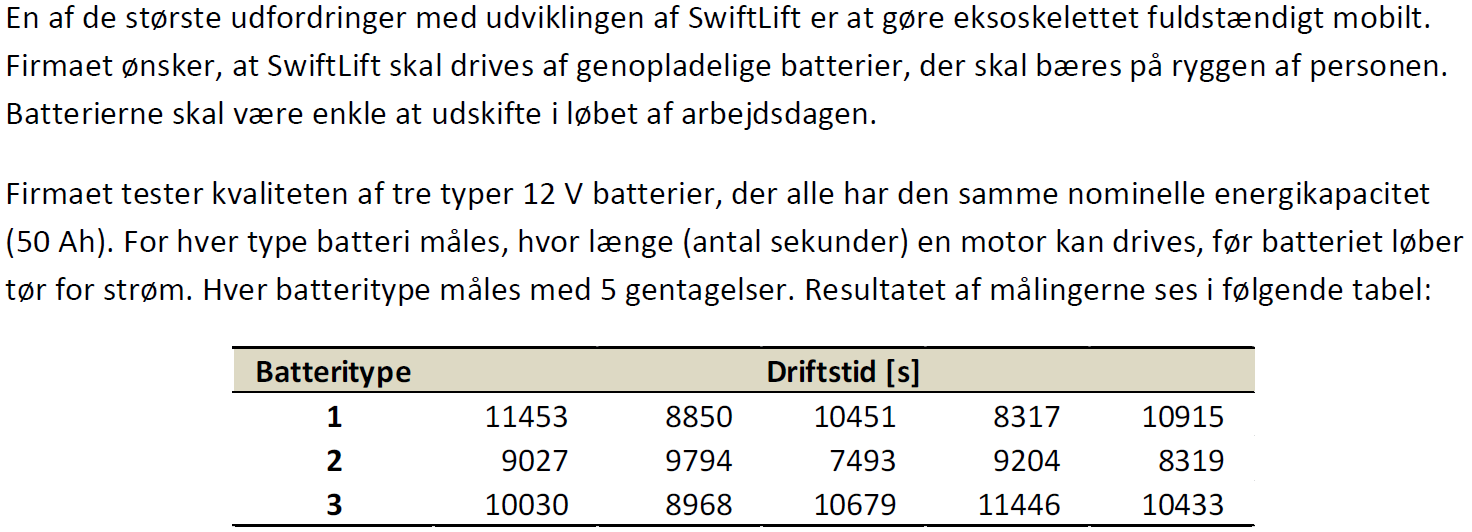

### a)

Lav og kommenter et parallelt boksplot, der viser driftstiden for hver batteritype.

clear
data = xlsread("Eksamens sæt\18E\Data_M4STI1_2018E.xlsx");
bat1 = data(1:5,4)

bat1 =        11453
        8850
       10451
        8317
       10915


bat2 = data(6:10,4)

bat2 =         9027
        9794
        7493
        9204
        8319


bat3 = data(11:15,4)

bat3 =        10030
        8968
       10679
       11446
       10433


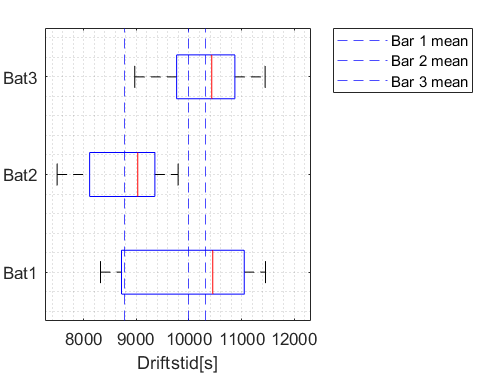


boxplot(data(1:15,4),data(1:15,3), 'Orientation','horizontal', ...
     "Labels", {'Bat1', 'Bat2', 'Bat3'})
xline(mean(bat1), '--b', 'DisplayName', 'Bar 1 mean')
xline(mean(bat2), '--b', 'DisplayName', 'Bar 2 mean')
xline(mean(bat3), '--b', 'DisplayName', 'Bar 3 mean')
xlabel('Driftstid[s]')
legend('location', 'northeastoutside')
grid("minor")


help legend

  legend Create legend
  
  legend creates a legend with descriptive labels for each plotted data
  series. For the labels, the legend uses the text from the DisplayName
  properties of the data series. If the DisplayName property is empty, then
  the legend uses a label of the form 'dataN'. The legend automatically
  updates when you add or delete data series from the axes. This command
  creates a legend for the current axes or chart returned by gca. If the
  current axes is empty, then the legend is empty. If axes do not exist,
  then this command creates one.
 
  legend(label1,...,labelN) sets the labels. Specify the labels as a list
  of character vectors, such as legend('Jan','Feb','Mar'). When you specify
  a label as an empty character vector or an empty string, the
  corresponding entry is omitted from the legend.
 
  legend(labels) sets the labels using a cell array of character vectors or
  a character matri

### b)

Undersøg i en variansanalyse med 5 % signifikansniveau, om batterierne har samme driftstid.

### c)

Lav en parvis sammenligning af batterierne, stadig med 5 % signifikansniveau.

### d)

Hvilke antagelser er der gjort for residualerne i variansanalysen? Undersøg om antagelserne er overholdt.

### e)

Hvilken type batteri vil du vælge som det bedste? Argumentér for dit valg.

Brembo = data(:,5)

Brembo =    70.3000
   86.7000
   77.9000
   75.0000
   79.7000
   73.9000
   80.9000
   78.2000
   91.9000
   86.7000


leng = length(Brembo)

leng = 24




interval = (ceil(max(Brembo)) - floor(min(Brembo)))/7

interval = 3.4286

bins = floor(min(Brembo)):interval:ceil(max(Brembo))

bins =    68.0000   71.4286   74.8571   78.2857   81.7143   85.1429   88.5714   92.0000



stemleafplot(Brembo,-1)

  68 | 5
  69 |
  70 | 3
  71 |
  72 |
  73 | 9
  74 | 0
  75 | 0
  76 |
  77 | 9
  78 | 2 6
  79 | 6 7 7
  80 | 9
  81 | 4 8
  82 | 6 6
  83 | 2
  84 | 3 7
  85 | 4
  86 | 7 7
  87 |
  88 | 9
  89 |
  90 |
  91 | 9
key: 36|5 = 36.5
stem unit: 1.0
leaf unit: 0.1


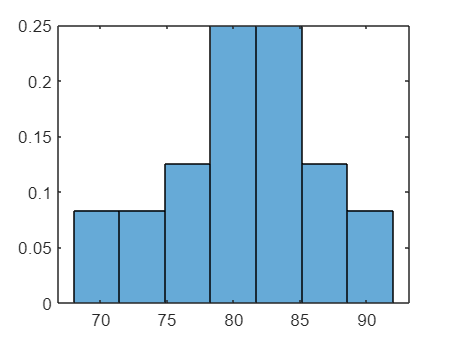


histogram(Brembo, bins, "Normalization","probability")

middel = mean(Brembo)

middel = 80.6875

Median = median(Brembo)

Median = 81.1500

sigma_2 = var(Brembo)

sigma_2 = 31.8811

sigma = std(Brembo)

sigma = 5.6463

data_min = min(Brembo)

data_min = 68.5000

data_max = max(Brembo)

data_max = 91.9000

Cl = data(:,5)

Cl =    70.3000
   86.7000
   77.9000
   75.0000
   79.7000
   73.9000
   80.9000
   78.2000
   91.9000
   86.7000


leng = length(Cl)

leng = 24

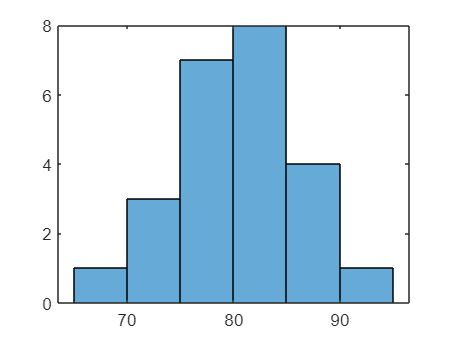


histogram(Cl)

middel = mean(Cl)

middel = 80.6875

Median = median(Cl)

Median = 81.1500

sigma_2 = var(Cl)

sigma_2 = 31.8811

sigma = std(Cl)

sigma = 5.6463

data_min = min(Cl)

data_min = 68.5000

data_max = max(Cl)

data_max = 91.9000